# Pseudocolor Image Processing

    Pemrosesan gambar pseudocolor (false-color) terdiri dari pemberian warna ke nilai abu-abu berdasarkan kriteria yang ditentukan. Istilah pseudo atau false color digunakan untuk membedakan proses pemberian warna pada gambar monokrom dari proses yang terkait dengan gambar berwarna asli.

## Membaca Gambar

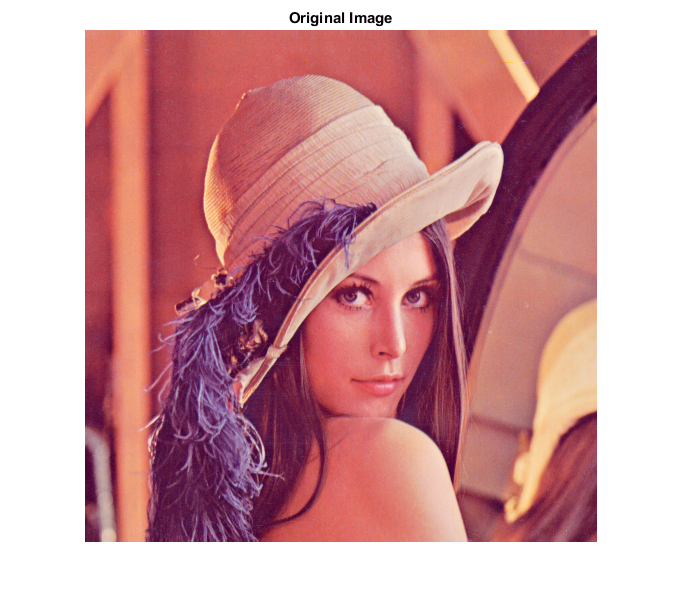

I = imread('./Input/Lena.tif');
imshow(I);
title('Original Image');

## Intensity Slicing

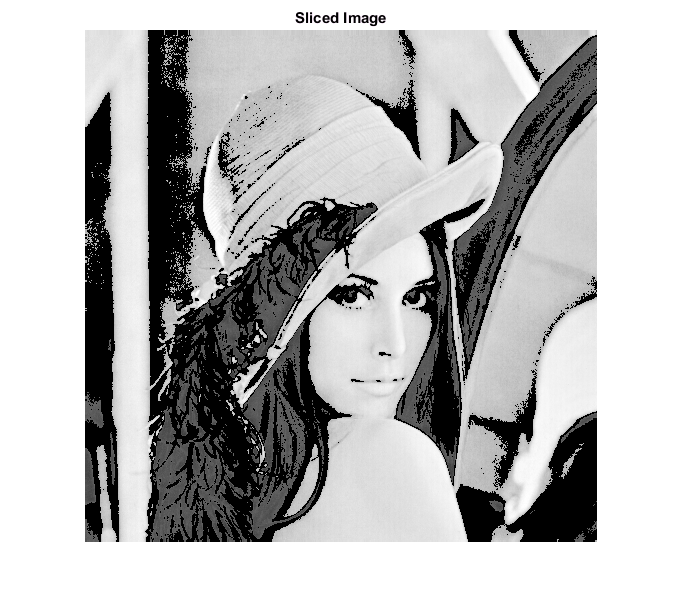

image = I(:,:,1);
rangeMin = 100;
rangeMax = 180;
[row,col]= size(image);
result = zeros(row,col);

for i = 1:row
    for j = 1:col
        if (rangeMin < image(i,j)&& image(i,j) < rangeMax)
            result(i,j) = 0;
        else
            result(i,j) = image(i,j);
        end
    end
end

imwrite(result,'.\Output\Lena_slicing.tif');
imshow(uint8(result))
title('Sliced Image');

## Perbandingan

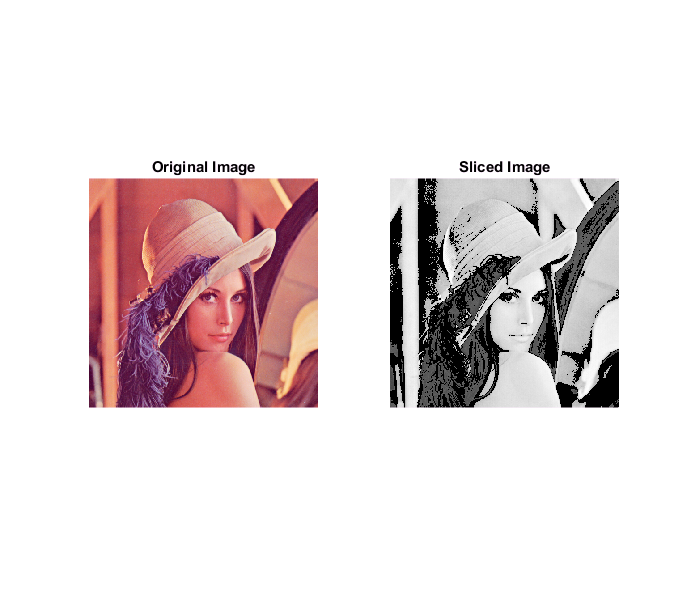

subplot(1,2,1); imshow(I)
title('Original Image');
subplot(1,2,2); imshow(uint8(result))
title('Sliced Image');